# System Identification (GPC)

## 0. Helpers

function [theta, yhat, ehat, info] = carima_els_mimo(y, u, na, nb, nc, d, maxIter, tol)
% Extended Least Squares for MIMO incremental CARIMA/ARMAX:
% y(k) = -A1 y(k-1)-...-Ana y(k-na) + B0 u(k-1-d)+...+Bnb u(k-1-d-nb)
%        + C1 e(k-1)+...+Cnc e(k-nc) + e(k)

    [N, ny] = size(y);
    nu = size(u,2);

    nAy = ny * na;
    nBu = nu * (nb + 1);
    nCe = ny * nc;
    nTheta = nAy + nBu + nCe;

    k0 = max([na, nb + d + 1, nc]) + 1;

    % --- ARX initialization (C = I, i.e., no MA terms) ---
    theta = zeros(nTheta, ny);
    theta_arx = arx_ls_mimo(y, u, na, nb, d);
    theta(1:nAy+nBu, :) = theta_arx;

    % Initial residuals from ARX predictor
    [yhat, ehat] = carima_osa_predict_mimo(y, u, theta, na, nb, nc, d);

    info.cost = nan(maxIter,1);
    info.relchg = nan(maxIter,1);

    for iter = 1:maxIter
        S = zeros(nTheta, nTheta);
        rhs = zeros(nTheta, ny);

        for k = k0:N
            phi_y = reshape(-y(k-1:-1:k-na, :).', [], 1);  % ny*na x 1
            phi_u = reshape( u(k-1-d:-1:k-1-d-nb, :).', [], 1); % nu*(nb+1) x 1
            if nc > 0
                phi_e = reshape(ehat(k-1:-1:k-nc, :).', [], 1); % ny*nc x 1
                phi = [phi_y; phi_u; phi_e];
            else
                phi = [phi_y; phi_u];
            end

            S = S + phi * phi.';
            rhs = rhs + phi * y(k,:);
        end

        % small regularization for numerical robustness
        theta_new = (S + 1e-6 * eye(nTheta)) \ rhs;

        [yhat_new, ehat_new] = carima_osa_predict_mimo(y, u, theta_new, na, nb, nc, d);

        idx = k0:N;
        cost = norm(ehat_new(idx,:), "fro")^2;
        relchg = norm(theta_new - theta, "fro") / max(1, norm(theta, "fro"));

        info.cost(iter) = cost;
        info.relchg(iter) = relchg;

        theta = theta_new;
        yhat = yhat_new;
        ehat = ehat_new;

        if relchg < tol
            break;
        end
    end

    info.nIter = iter;
    info.cost = info.cost(1:iter);
    info.relchg = info.relchg(1:iter);
end


function theta_arx = arx_ls_mimo(y, u, na, nb, d)
% Least-squares ARX initializer (no noise polynomial terms)
    [N, ny] = size(y);
    nu = size(u,2);

    nAy = ny * na;
    nBu = nu * (nb + 1);
    nTheta = nAy + nBu;

    k0 = max([na, nb + d + 1]) + 1;

    S = zeros(nTheta, nTheta);
    rhs = zeros(nTheta, ny);

    for k = k0:N
        phi_y = reshape(-y(k-1:-1:k-na, :).', [], 1);
        phi_u = reshape( u(k-1-d:-1:k-1-d-nb, :).', [], 1);
        phi = [phi_y; phi_u];

        S = S + phi * phi.';
        rhs = rhs + phi * y(k,:);
    end

    theta_arx = (S + 1e-10 * eye(nTheta)) \ rhs;
end


function [yhat, ehat, k0] = carima_osa_predict_mimo(y, u, theta, na, nb, nc, d)
% One-step-ahead predictor for MIMO ARMAX/CARIMA incremental model
% Uses recursively computed innovations ehat in the C(q^-1) term.

    [N, ny] = size(y);
    nu = size(u,2);

    nAy = ny * na;
    nBu = nu * (nb + 1);
    nCe = ny * nc;
    nTheta = nAy + nBu + nCe;

    if size(theta,1) ~= nTheta || size(theta,2) ~= ny
        error("theta size mismatch. Expected [%d x %d], got [%d x %d].", ...
            nTheta, ny, size(theta,1), size(theta,2));
    end

    yhat = nan(N, ny);
    ehat = zeros(N, ny);

    k0 = max([na, nb + d + 1, nc]) + 1;

    for k = k0:N
        phi_y = reshape(-y(k-1:-1:k-na, :).', [], 1);
        phi_u = reshape( u(k-1-d:-1:k-1-d-nb, :).', [], 1);

        if nc > 0
            phi_e = reshape(ehat(k-1:-1:k-nc, :).', [], 1);
            phi = [phi_y; phi_u; phi_e];
        else
            phi = [phi_y; phi_u];
        end

        yhat(k,:) = (phi.' * theta);   % 1 x ny
        ehat(k,:) = y(k,:) - yhat(k,:);
    end
end

## 1. Load + format data

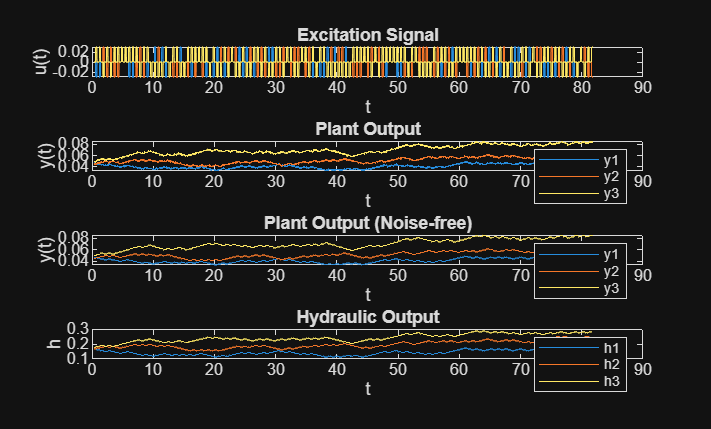

data_path = fullfile("data", "noise", "IdMPC_est.mat");
Ts = 0.02;
load(data_path);
% Drop the first sample
startIdx = 20;
t = t(startIdx:end, :);
u = u(startIdx:end, :);
y = y(startIdx:end, :);
y_real = y_real(startIdx:end, :);
l_hy = l_hy(startIdx:end, :);

figure;
subplot(4, 1, 1);
plot(t, u);
title('Excitation Signal'); xlabel('t'); ylabel('u(t)');
subplot(4, 1, 2);
plot(t, y);
title('Plant Output'); xlabel('t'); ylabel('y(t)');
legend("y1", "y2", "y3");
subplot(4, 1, 3);
plot(t, y_real);
title('Plant Output (Noise-free)'); xlabel('t'); ylabel('y(t)');
legend("y1", "y2", "y3");
subplot(4, 1, 4);
plot(t, l_hy);
title('Hydraulic Output'); xlabel('t'); ylabel('h');
legend("h1", "h2", "h3");

## 2. Create `iddata` + detrend

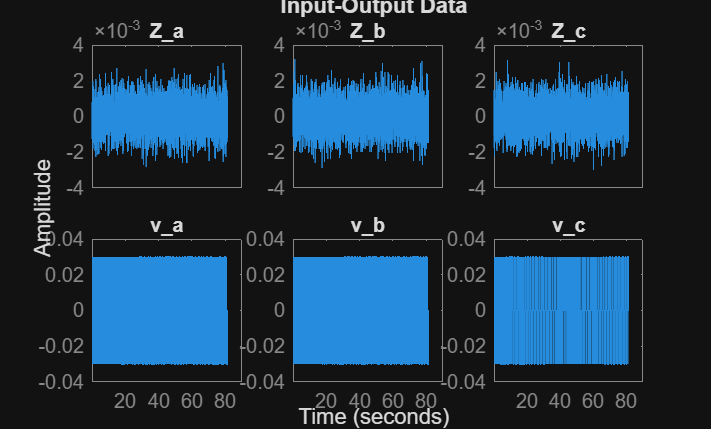

y = diff(y);
% y = diff(y_real);
u = diff(u);

data = iddata(y, u, Ts, "TimeUnit", "s");
data.InputName = {"v_a", "v_b", "v_c"};
data.OutputName = {"Z_a", "Z_b", "Z_c"};

% remove mean
% data = detrend(data, 0);

figure;
idplot(data);

## 3. Split estimation/validation

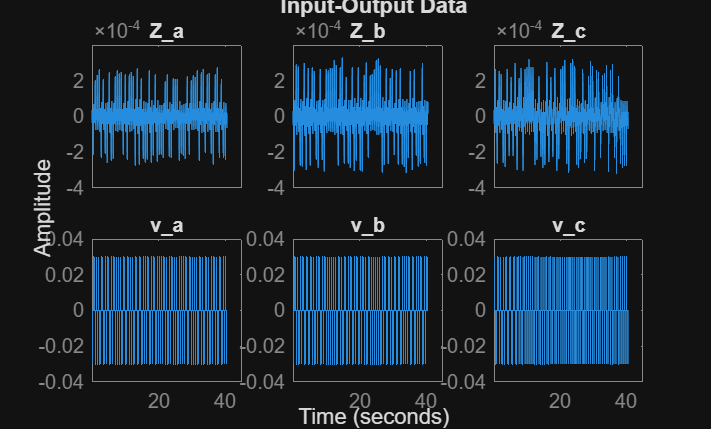

% N = size(data.OutputData, 1);
% Ne = floor(0.7*N);
% 
% data_est = data(1:Ne);
% data_val = data(Ne+1:end);

data_est = data;
data_path = fullfile("data", "noise", "IdMPC_val.mat");
load(data_path);
t = t(startIdx:end, :);
u = u(startIdx:end, :);
% y = y(startIdx:end, :);
y = y_real(startIdx:end, :);
l_hy = l_hy(startIdx:end, :);

u = diff(u);
y = diff(y);

data_val = iddata(y, u, Ts, "TimeUnit", "s");
data_val.InputName = {"v_a", "v_b", "v_c"};
data_val.OutputName = {"Z_a", "Z_b", "Z_c"};
figure;
idplot(data_val);

## 4. Estimate CARIMA model

y_est = data_est.y;   % these are already diff(y)
u_est = data_est.u;   % these are already diff(u)
y_val = data_val.y;
u_val = data_val.u;

n_a = 2:10;
n_b = 1:10;
n_c = 0:2;    % <-- noise polynomial order C(q^-1) = 1 + c1 q^-1 + ... + cnc q^-nc
d   = 0;      % input delay
maxELSIter = 20;
tolELS = 1e-4;

fit_best = -Inf;
theta_best = [];
na_best = 0; nb_best = 0; nc_best = 0;

for na = n_a
    for nb = n_b
        for nc = n_c
            try
                [theta_hat, yhat_est, ehat_est, info] = carima_els_mimo( ...
                    y_est, u_est, na, nb, nc, d, maxELSIter, tolELS);

                % One-step-ahead validation prediction (uses noise model recursively)
                [yhat_val, ~, k0] = carima_osa_predict_mimo( ...
                    y_val, u_val, theta_hat, na, nb, nc, d);

                idx = k0:size(y_val,1);
                fit = 100 * (1 - norm(y_val(idx,:) - yhat_val(idx,:)) / ...
                    norm(y_val(idx,:) - mean(y_val(idx,:),1)));

                fprintf("na=%d, nb=%d, nc=%d, fit=%.2f%%, ELS iters=%d\n", ...
                    na, nb, nc, fit, info.nIter);

                if fit > fit_best + 0.1
                    fit_best = fit;
                    theta_best = theta_hat;
                    na_best = na;
                    nb_best = nb;
                    nc_best = nc;
                    info_best = info;
                end
            catch ME
                fprintf("na=%d, nb=%d, nc=%d failed: %s\n", na, nb, nc, ME.message);
            end
        end
    end
end

na=2, nb=1, nc=0, fit=-78.17%, ELS iters=2
na=2, nb=1, nc=1, fit=-127.99%, ELS iters=12
na=2, nb=1, nc=2, fit=-131.64%, ELS iters=11
na=2, nb=2, nc=0, fit=-76.81%, ELS iters=2
na=2, nb=2, nc=1, fit=-124.61%, ELS iters=15
na=2, nb=2, nc=2, fit=-129.55%, ELS iters=13
na=2, nb=3, nc=0, fit=-77.00%, ELS iters=2
na=2, nb=3, nc=1, fit=-126.49%, ELS iters=20
na=2, nb=3, nc=2, fit=-129.13%, ELS iters=20
na=2, nb=4, nc=0, fit=-76.72%, ELS iters=2
na=2, nb=4, nc=1, fit=-125.67%, ELS iters=20
na=2, nb=4, nc=2, fit=-130.24%, ELS iters=20
na=2, nb=5, nc=0, fit=-73.31%, ELS iters=2
na=2, nb=5, nc=1, fit=-127.95%, ELS iters=20
na=2, nb=5, nc=2, fit=-169.08%, ELS iters=20
na=2, nb=6, nc=0, fit=-64.75%, ELS iters=2
na=2, nb=6, nc=1, fit=-146.06%, ELS iters=20
na=2, nb=6, nc=2, fit=-181.76%, ELS iters=20
na=2, nb=7, nc=0, fit=-52.88%, ELS iters=2
na=2, nb=7, nc=1, fit=-151.06%, ELS iters=20


na=2, nb=7, nc=2, fit=NaN%, ELS iters=20
na=2, nb=8, nc=0, fit=-38.24%, ELS iters=2
na=2, nb=8, nc=1, fit=-179.16%, ELS iters=20
na=2, nb=8, nc=2, fit=-132.89%, ELS iters=20
na=2, nb=9, nc=0, fit=-24.51%, ELS iters=2
na=2, nb=9, nc=1, fit=-276.78%, ELS iters=20
na=2, nb=9, nc=2, fit=-128.41%, ELS iters=20
na=2, nb=10, nc=0, fit=-20.62%, ELS iters=2
na=2, nb=10, nc=1, fit=-220.61%, ELS iters=20
na=2, nb=10, nc=2, fit=-107.34%, ELS iters=20
na=3, nb=1, nc=0, fit=-100.36%, ELS iters=2
na=3, nb=1, nc=1, fit=-128.32%, ELS iters=20
na=3, nb=1, nc=2, fit=-129.56%, ELS iters=20
na=3, nb=2, nc=0, fit=-99.10%, ELS iters=2
na=3, nb=2, nc=1, fit=-125.42%, ELS iters=20
na=3, nb=2, nc=2, fit=-127.67%, ELS iters=16
na=3, nb=3, nc=0, fit=-98.96%, ELS iters=2
na=3, nb=3, nc=1, fit=-128.95%, ELS iters=20
na=3, nb=3, nc=2, fit=-128.68%, ELS iters=20
na=3, nb=4, nc=0, fit=-99.02%, ELS iters=2
na=3, nb=4, nc=1, fit=-175.67%, ELS iters=20


na=3, nb=4, nc=2, fit=NaN%, ELS iters=20
na=3, nb=5, nc=0, fit=-96.04%, ELS iters=2
na=3, nb=5, nc=1, fit=-215019480057916180815310726056902656000.00%, ELS iters=20


na=3, nb=5, nc=2, fit=NaN%, ELS iters=20
na=3, nb=6, nc=0, fit=-88.36%, ELS iters=2
na=3, nb=6, nc=1, fit=-247.32%, ELS iters=20
na=3, nb=6, nc=2, fit=-113.34%, ELS iters=20
na=3, nb=7, nc=0, fit=-76.36%, ELS iters=2
na=3, nb=7, nc=1, fit=-245.94%, ELS iters=20


na=3, nb=7, nc=2, fit=-76.43%, ELS iters=20
na=3, nb=8, nc=0, fit=-61.01%, ELS iters=2
na=3, nb=8, nc=1, fit=-123.45%, ELS iters=20
na=3, nb=8, nc=2, fit=-203.49%, ELS iters=20
na=3, nb=9, nc=0, fit=-45.88%, ELS iters=2
na=3, nb=9, nc=1, fit=-159.17%, ELS iters=20
na=3, nb=9, nc=2, fit=-113.92%, ELS iters=20
na=3, nb=10, nc=0, fit=-40.90%, ELS iters=2
na=3, nb=10, nc=1, fit=-313.79%, ELS iters=20
na=3, nb=10, nc=2, fit=-101.96%, ELS iters=20
na=4, nb=1, nc=0, fit=-116.83%, ELS iters=2
na=4, nb=1, nc=1, fit=-122.01%, ELS iters=20
na=4, nb=1, nc=2, fit=-121.44%, ELS iters=20
na=4, nb=2, nc=0, fit=-116.04%, ELS iters=2
na=4, nb=2, nc=1, fit=-126.42%, ELS iters=20
na=4, nb=2, nc=2, fit=-114.45%, ELS iters=20
na=4, nb=3, nc=0, fit=-115.93%, ELS iters=2
na=4, nb=3, nc=1, fit=-127.17%, ELS iters=20
na=4, nb=3, nc=2, fit=-125.84%, ELS iters=20
na=4, nb=4, nc=0, fit=-116.13%, ELS iters=2


na=4, nb=4, nc=1, fit=NaN%, ELS iters=20


na=4, nb=4, nc=2, fit=NaN%, ELS iters=20
na=4, nb=5, nc=0, fit=-113.71%, ELS iters=2


na=4, nb=5, nc=1, fit=NaN%, ELS iters=20


na=4, nb=5, nc=2, fit=NaN%, ELS iters=20
na=4, nb=6, nc=0, fit=-106.60%, ELS iters=2


na=4, nb=6, nc=1, fit=NaN%, ELS iters=20


na=4, nb=6, nc=2, fit=NaN%, ELS iters=20
na=4, nb=7, nc=0, fit=-95.91%, ELS iters=2
na=4, nb=7, nc=1, fit=-187.42%, ELS iters=20


na=4, nb=7, nc=2, fit=-95.98%, ELS iters=20
na=4, nb=8, nc=0, fit=-81.54%, ELS iters=2
na=4, nb=8, nc=1, fit=-105.16%, ELS iters=20


na=4, nb=8, nc=2, fit=-81.63%, ELS iters=20
na=4, nb=9, nc=0, fit=-66.78%, ELS iters=2
na=4, nb=9, nc=1, fit=-125.67%, ELS iters=20
na=4, nb=9, nc=2, fit=-97.69%, ELS iters=20
na=4, nb=10, nc=0, fit=-61.44%, ELS iters=2
na=4, nb=10, nc=1, fit=-91.35%, ELS iters=20
na=4, nb=10, nc=2, fit=-99.05%, ELS iters=20
na=5, nb=1, nc=0, fit=-124.06%, ELS iters=2
na=5, nb=1, nc=1, fit=-126.28%, ELS iters=20
na=5, nb=1, nc=2, fit=-8394214830398034772169761962988929631624697808400988437398311974393861763512148156917460935358272802743492745571445852290074627973089207467511997588844637669398526869923306240156039074326210694970446184448.00%, ELS iters=20
na=5, nb=2, nc=0, fit=-123.93%, ELS iters=2
na=5, nb=2, nc=1, fit=-126.42%, ELS iters=20
na=5, nb=2, nc=2, fit=-122.96%, ELS iters=20
na=5, nb=3, nc=0, fit=-123.95%, ELS iters=2
na=5, nb=3, nc=1, fit=-125.15%, ELS iters=20
na=5, nb=3, nc=2, fit=-126.24%, ELS iters=20
na=5, nb=4, nc=0, fit=-124.27%, ELS iters=2


na=5, nb=4, nc=1, fit=NaN%, ELS iters=20
na=5, nb=4, nc=2, fit=-123.08%, ELS iters=20
na=5, nb=5, nc=0, fit=-121.89%, ELS iters=2


na=5, nb=5, nc=1, fit=-122.01%, ELS iters=20


na=5, nb=5, nc=2, fit=NaN%, ELS iters=20
na=5, nb=6, nc=0, fit=-115.54%, ELS iters=2


na=5, nb=6, nc=1, fit=-19598978240369167674497826816.00%, ELS iters=20


na=5, nb=6, nc=2, fit=NaN%, ELS iters=20
na=5, nb=7, nc=0, fit=-105.42%, ELS iters=2


na=5, nb=7, nc=1, fit=NaN%, ELS iters=20


na=5, nb=7, nc=2, fit=-105.52%, ELS iters=20
na=5, nb=8, nc=0, fit=-92.92%, ELS iters=2
na=5, nb=8, nc=1, fit=-218.10%, ELS iters=20


na=5, nb=8, nc=2, fit=-93.04%, ELS iters=20
na=5, nb=9, nc=0, fit=-79.63%, ELS iters=2
na=5, nb=9, nc=1, fit=-304.25%, ELS iters=20
na=5, nb=9, nc=2, fit=-99.71%, ELS iters=20
na=5, nb=10, nc=0, fit=-74.86%, ELS iters=2
na=5, nb=10, nc=1, fit=-102.13%, ELS iters=20
na=5, nb=10, nc=2, fit=-107.00%, ELS iters=20
na=6, nb=1, nc=0, fit=-124.92%, ELS iters=2
na=6, nb=1, nc=1, fit=-124.87%, ELS iters=20


na=6, nb=1, nc=2, fit=-124.92%, ELS iters=20
na=6, nb=2, nc=0, fit=-125.96%, ELS iters=2
na=6, nb=2, nc=1, fit=-125.85%, ELS iters=20
na=6, nb=2, nc=2, fit=-125.20%, ELS iters=20
na=6, nb=3, nc=0, fit=-126.21%, ELS iters=2
na=6, nb=3, nc=1, fit=-124.96%, ELS iters=20


na=6, nb=3, nc=2, fit=-126.62%, ELS iters=20
na=6, nb=4, nc=0, fit=-126.46%, ELS iters=2


na=6, nb=4, nc=1, fit=NaN%, ELS iters=20


na=6, nb=4, nc=2, fit=-126.69%, ELS iters=20
na=6, nb=5, nc=0, fit=-123.83%, ELS iters=2


na=6, nb=5, nc=1, fit=NaN%, ELS iters=20


na=6, nb=5, nc=2, fit=NaN%, ELS iters=20
na=6, nb=6, nc=0, fit=-116.54%, ELS iters=2


na=6, nb=6, nc=1, fit=NaN%, ELS iters=20


na=6, nb=6, nc=2, fit=NaN%, ELS iters=20
na=6, nb=7, nc=0, fit=-106.69%, ELS iters=2


na=6, nb=7, nc=1, fit=NaN%, ELS iters=20


na=6, nb=7, nc=2, fit=NaN%, ELS iters=20
na=6, nb=8, nc=0, fit=-94.57%, ELS iters=2


na=6, nb=8, nc=1, fit=-447075408187525271281893113856.00%, ELS iters=20


na=6, nb=8, nc=2, fit=-94.77%, ELS iters=20
na=6, nb=9, nc=0, fit=-83.32%, ELS iters=2


na=6, nb=9, nc=1, fit=-83.47%, ELS iters=20


na=6, nb=9, nc=2, fit=-83.49%, ELS iters=20
na=6, nb=10, nc=0, fit=-79.53%, ELS iters=2
na=6, nb=10, nc=1, fit=-76.89%, ELS iters=20


na=6, nb=10, nc=2, fit=-108.02%, ELS iters=20
na=7, nb=1, nc=0, fit=-123.46%, ELS iters=2
na=7, nb=1, nc=1, fit=-123.29%, ELS iters=20
na=7, nb=1, nc=2, fit=-127.68%, ELS iters=20
na=7, nb=2, nc=0, fit=-125.00%, ELS iters=2
na=7, nb=2, nc=1, fit=-125.20%, ELS iters=20


na=7, nb=2, nc=2, fit=NaN%, ELS iters=20
na=7, nb=3, nc=0, fit=-125.44%, ELS iters=2
na=7, nb=3, nc=1, fit=-125.63%, ELS iters=20


na=7, nb=3, nc=2, fit=-125.61%, ELS iters=20
na=7, nb=4, nc=0, fit=-125.54%, ELS iters=2


na=7, nb=4, nc=1, fit=NaN%, ELS iters=20


na=7, nb=4, nc=2, fit=NaN%, ELS iters=20
na=7, nb=5, nc=0, fit=-122.43%, ELS iters=2


na=7, nb=5, nc=1, fit=NaN%, ELS iters=20


na=7, nb=5, nc=2, fit=NaN%, ELS iters=20
na=7, nb=6, nc=0, fit=-114.05%, ELS iters=2


na=7, nb=6, nc=1, fit=-114.00%, ELS iters=20


na=7, nb=6, nc=2, fit=NaN%, ELS iters=20
na=7, nb=7, nc=0, fit=-102.73%, ELS iters=2


na=7, nb=7, nc=1, fit=NaN%, ELS iters=20


na=7, nb=7, nc=2, fit=NaN%, ELS iters=20
na=7, nb=8, nc=0, fit=-90.22%, ELS iters=2


na=7, nb=8, nc=1, fit=NaN%, ELS iters=20


na=7, nb=8, nc=2, fit=-90.30%, ELS iters=20
na=7, nb=9, nc=0, fit=-78.75%, ELS iters=2


na=7, nb=9, nc=1, fit=-78.86%, ELS iters=20


na=7, nb=9, nc=2, fit=-78.90%, ELS iters=20
na=7, nb=10, nc=0, fit=-75.46%, ELS iters=2


na=7, nb=10, nc=1, fit=NaN%, ELS iters=20


na=7, nb=10, nc=2, fit=-4303430534512183476065775735867686868194206868591063717794189023740166144.00%, ELS iters=20
na=8, nb=1, nc=0, fit=-124.11%, ELS iters=2
na=8, nb=1, nc=1, fit=-134.33%, ELS iters=20


na=8, nb=1, nc=2, fit=-12504789438709204731413666364202250358184256369437179904.00%, ELS iters=20
na=8, nb=2, nc=0, fit=-125.72%, ELS iters=2
na=8, nb=2, nc=1, fit=-126.79%, ELS iters=20
na=8, nb=2, nc=2, fit=-131.39%, ELS iters=20
na=8, nb=3, nc=0, fit=-126.21%, ELS iters=2
na=8, nb=3, nc=1, fit=-126.23%, ELS iters=20


na=8, nb=3, nc=2, fit=NaN%, ELS iters=20
na=8, nb=4, nc=0, fit=-126.35%, ELS iters=2


na=8, nb=4, nc=1, fit=NaN%, ELS iters=20


na=8, nb=4, nc=2, fit=NaN%, ELS iters=20
na=8, nb=5, nc=0, fit=-123.41%, ELS iters=2


na=8, nb=5, nc=1, fit=NaN%, ELS iters=20


na=8, nb=5, nc=2, fit=NaN%, ELS iters=20
na=8, nb=6, nc=0, fit=-114.83%, ELS iters=2


na=8, nb=6, nc=1, fit=-114.92%, ELS iters=20


na=8, nb=6, nc=2, fit=NaN%, ELS iters=20
na=8, nb=7, nc=0, fit=-102.80%, ELS iters=2


na=8, nb=7, nc=1, fit=-102.83%, ELS iters=20


na=8, nb=7, nc=2, fit=NaN%, ELS iters=20
na=8, nb=8, nc=0, fit=-89.13%, ELS iters=2


na=8, nb=8, nc=1, fit=-89.15%, ELS iters=20


na=8, nb=8, nc=2, fit=NaN%, ELS iters=20
na=8, nb=9, nc=0, fit=-77.25%, ELS iters=2


na=8, nb=9, nc=1, fit=-57316657507632863852515325652009357761994967077902876672.00%, ELS iters=20


na=8, nb=9, nc=2, fit=-77.29%, ELS iters=20
na=8, nb=10, nc=0, fit=-73.13%, ELS iters=2


na=8, nb=10, nc=1, fit=-150.33%, ELS iters=20


na=8, nb=10, nc=2, fit=-73.23%, ELS iters=20
na=9, nb=1, nc=0, fit=-124.48%, ELS iters=2
na=9, nb=1, nc=1, fit=-128.80%, ELS iters=20


na=9, nb=1, nc=2, fit=NaN%, ELS iters=20
na=9, nb=2, nc=0, fit=-126.16%, ELS iters=2
na=9, nb=2, nc=1, fit=-127.00%, ELS iters=20


na=9, nb=2, nc=2, fit=-132.61%, ELS iters=20
na=9, nb=3, nc=0, fit=-126.71%, ELS iters=2
na=9, nb=3, nc=1, fit=-126.80%, ELS iters=20


na=9, nb=3, nc=2, fit=-71130227587962993600155403910599603611641784998427371094671360.00%, ELS iters=20
na=9, nb=4, nc=0, fit=-127.00%, ELS iters=2


na=9, nb=4, nc=1, fit=NaN%, ELS iters=20


na=9, nb=4, nc=2, fit=-126.93%, ELS iters=20
na=9, nb=5, nc=0, fit=-124.23%, ELS iters=2


na=9, nb=5, nc=1, fit=NaN%, ELS iters=20


na=9, nb=5, nc=2, fit=NaN%, ELS iters=20
na=9, nb=6, nc=0, fit=-115.49%, ELS iters=2


na=9, nb=6, nc=1, fit=-115.53%, ELS iters=20


na=9, nb=6, nc=2, fit=NaN%, ELS iters=20
na=9, nb=7, nc=0, fit=-102.81%, ELS iters=2


na=9, nb=7, nc=1, fit=NaN%, ELS iters=20


na=9, nb=7, nc=2, fit=NaN%, ELS iters=20
na=9, nb=8, nc=0, fit=-87.86%, ELS iters=2


na=9, nb=8, nc=1, fit=NaN%, ELS iters=20


na=9, nb=8, nc=2, fit=NaN%, ELS iters=20
na=9, nb=9, nc=0, fit=-74.41%, ELS iters=2


na=9, nb=9, nc=1, fit=NaN%, ELS iters=20


na=9, nb=9, nc=2, fit=NaN%, ELS iters=20
na=9, nb=10, nc=0, fit=-69.39%, ELS iters=2


na=9, nb=10, nc=1, fit=NaN%, ELS iters=20


na=9, nb=10, nc=2, fit=-90.41%, ELS iters=20
na=10, nb=1, nc=0, fit=-124.21%, ELS iters=2
na=10, nb=1, nc=1, fit=-126.97%, ELS iters=20
na=10, nb=1, nc=2, fit=-127.55%, ELS iters=20
na=10, nb=2, nc=0, fit=-125.86%, ELS iters=2
na=10, nb=2, nc=1, fit=-126.98%, ELS iters=20
na=10, nb=2, nc=2, fit=-133.05%, ELS iters=20
na=10, nb=3, nc=0, fit=-126.41%, ELS iters=2
na=10, nb=3, nc=1, fit=-126.02%, ELS iters=20


na=10, nb=3, nc=2, fit=-129.51%, ELS iters=20
na=10, nb=4, nc=0, fit=-126.80%, ELS iters=2


na=10, nb=4, nc=1, fit=NaN%, ELS iters=20


na=10, nb=4, nc=2, fit=NaN%, ELS iters=20
na=10, nb=5, nc=0, fit=-124.22%, ELS iters=2


na=10, nb=5, nc=1, fit=NaN%, ELS iters=20


na=10, nb=5, nc=2, fit=NaN%, ELS iters=20
na=10, nb=6, nc=0, fit=-115.48%, ELS iters=2


na=10, nb=6, nc=1, fit=NaN%, ELS iters=20


na=10, nb=6, nc=2, fit=NaN%, ELS iters=20
na=10, nb=7, nc=0, fit=-102.23%, ELS iters=2


na=10, nb=7, nc=1, fit=NaN%, ELS iters=20


na=10, nb=7, nc=2, fit=NaN%, ELS iters=20
na=10, nb=8, nc=0, fit=-85.99%, ELS iters=2


na=10, nb=8, nc=1, fit=NaN%, ELS iters=20


na=10, nb=8, nc=2, fit=NaN%, ELS iters=20
na=10, nb=9, nc=0, fit=-70.73%, ELS iters=2


na=10, nb=9, nc=1, fit=-70.74%, ELS iters=20


na=10, nb=9, nc=2, fit=NaN%, ELS iters=20
na=10, nb=10, nc=0, fit=-64.10%, ELS iters=2


na=10, nb=10, nc=1, fit=NaN%, ELS iters=20


na=10, nb=10, nc=2, fit=-64.65%, ELS iters=20



fprintf("\nBest orders: na=%d, nb=%d, nc=%d, fit=%.2f%%\n", ...
    na_best, nb_best, nc_best, fit_best);


Best orders: na=2, nb=10, nc=0, fit=-20.62%


## 5. Validate the model

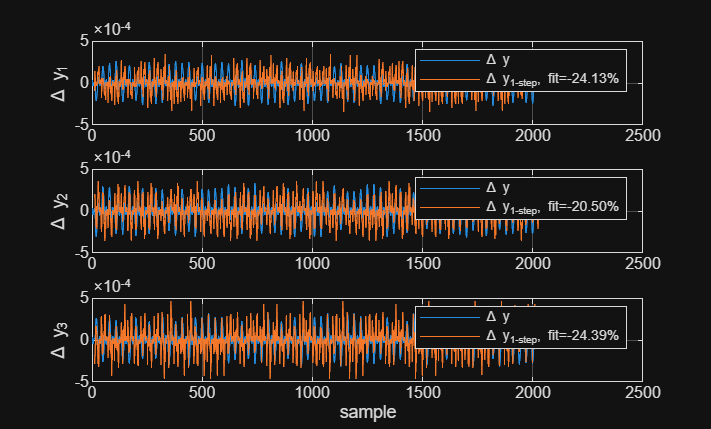

y = data_val.y;   % diff(y)
u = data_val.u;   % diff(u)

[y_hat, e_hat, k0] = carima_osa_predict_mimo(y, u, theta_best, na_best, nb_best, nc_best, d);

figure;
for i = 1:3
    fit_i = 100 * (1 - norm(y(k0:end,i) - y_hat(k0:end,i)) / ...
        norm(y(k0:end,i) - mean(y(k0:end,i))));
    subplot(3,1,i);
    plot(y(:,i)); hold on;
    plot(y_hat(:,i)); hold off;
    grid on;
    legend("\Delta y", sprintf("\\Delta y_{1-step}, fit=%.2f%%", fit_i));
    ylabel(sprintf("\\Delta y_%d",i));
end
xlabel("sample");

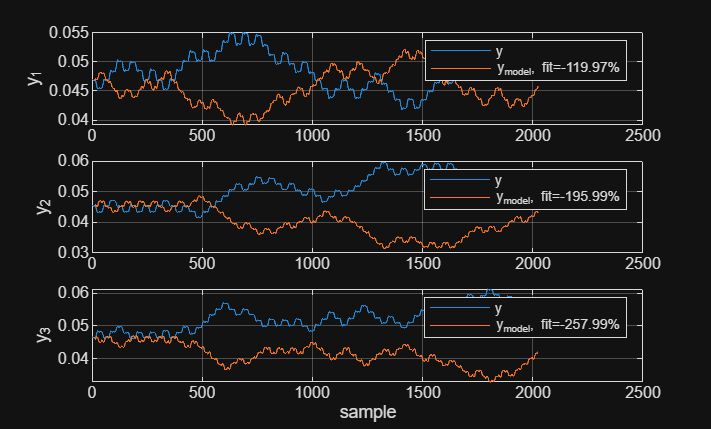


% reconstruct original y from predicted delta-y (one-step style)
% load("data/IdMPC_val.mat", "y_real");
% y_raw = y_real(startIdx:end, :);   % original (not differenced)
load("data/noise-free/IdMPC_val.mat", "y");
y_raw = y(startIdx:end, :);
y_model = nan(size(y_raw));

% Reconstruct from k0 onward using cumulative sum of predicted delta-y
y_model(k0,:) = y_raw(k0,:);
for k = k0+1:size(y_hat,1)
    y_model(k,:) = y_model(k-1,:) + y_hat(k,:);
end

figure;
for i = 1:3
    idx = k0:size(y_hat,1);
    fit_i = 100 * (1 - norm(y_raw(idx,i) - y_model(idx,i)) / ...
        norm(y_raw(idx,i) - mean(y_raw(idx,i))));
    subplot(3,1,i);
    plot(y_raw(:,i)); hold on;
    plot(y_model(:,i)); hold off;
    grid on;
    legend("y", sprintf("y_{model}, fit=%.2f%%", fit_i));
    ylabel(sprintf("y_%d",i));
end
xlabel("sample");

## 6. GPC parameters

% theta rows are ordered in 3x3 blocks:
% [A1 ... Ana, B0 ... Bnb, C1 ... Cnc]
ThetaBlk = reshape(theta_best', 3, 3, []);

A = cat(3, eye(3), ThetaBlk(:,:,1:na_best));
B = ThetaBlk(:,:,na_best+1 : na_best+nb_best+1);

if nc_best > 0
    C = cat(3, eye(3), ThetaBlk(:,:,na_best+nb_best+2 : na_best+nb_best+1+nc_best));
else
    C = eye(3);   % C(q^-1) = I
end

% save("data/GPC_params.mat", "A", "B", "C", "na_best", "nb_best", "nc_best", "d", "Ts");